# Controlador LQR

**Profesor:** PhD. Marlon Moscoso Martínez

%% Sección 1: Definición del Sistema y Parámetros LQR

% Limpiamos el entorno
clear; close all; clc;

% Matrices del sistema
A = [0 1;
     0 0];
B = [0;
     1];

% Definimos los pesos de la función de costo
Q = eye(2);   % Peso sobre los estados (posición y velocidad)
R = 1;        % Peso sobre la señal de control

% Calculamos la realimentación óptima K usando la función lqr
K = lqr(A, B, Q, R);

disp('Matriz de realimentación K:');

Matriz de realimentación K:


disp(K);

    1.0000    1.7321



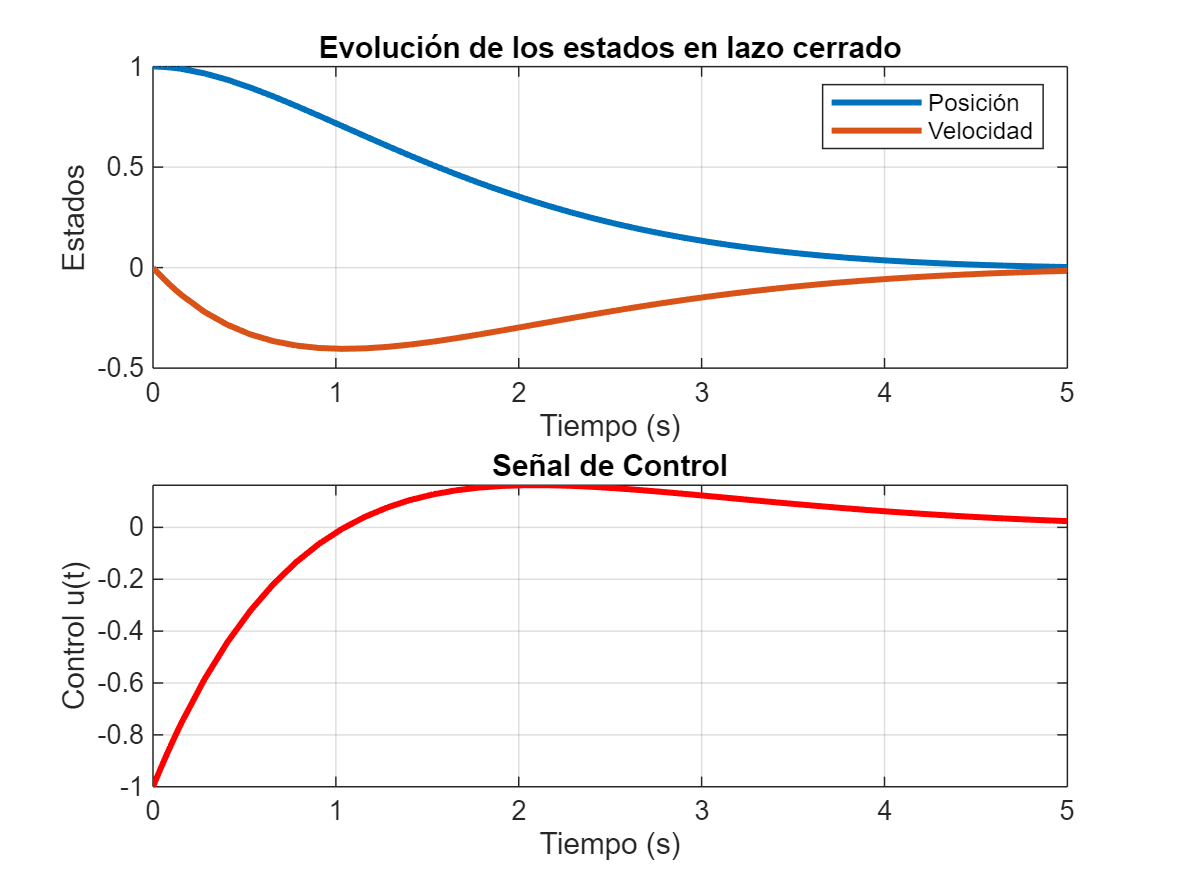


%% Sección 2: Simulación en lazo cerrado

% Definimos la dinámica en lazo cerrado: x_dot = (A - B*K)*x
A_cl = A - B*K;

% Tiempo de simulación
tspan = [0 5];

% Condición inicial (por ejemplo, posición = 1 m y velocidad = 0 m/s)
x0 = [1; 0];

% Usamos ODE45 para simular
[t, x] = ode45(@(t,x) A_cl*x, tspan, x0);

% Calculamos la señal de control en cada instante
u = - (K * x')';

%% Sección 3: Gráficas de resultados

% Gráfica de la evolución de los estados (posición y velocidad)
figure;
subplot(2,1,1);
plot(t, x(:,1), 'LineWidth', 2);
hold on; grid on;
plot(t, x(:,2), 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Estados');
legend('Posición', 'Velocidad');
title('Evolución de los estados en lazo cerrado');

% Gráfica de la señal de control
subplot(2,1,2);
plot(t, u, 'r', 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Control u(t)');
grid on;
title('Señal de Control');